Practice Problems 8 - Nonlinear Regression & Symbolic Toolbox

1) Fit a cubic polynomial to the following data by extending the system of equations on lecture slide 3, then calculate the standard error and correlation coefficient. Graph the data and your fitting equation.

x1 = [3, 4, 5, 7, 8, 9, 11, 12];
y1 = [1.6, 3.6, 4.4, 3.4, 2.2, 2.8, 3.8, 4.6];
p1 = polyfit(x1, y1, 3);

% Calculate Standard Error
sr = 0;
st = 0;

% Perform Summation to find Sr and St
for m = 1:length(y1)
    sr = sr + (- x1(m)^3 * p1(1) - x1(m)^2 * p1(2) - x1(m) * p1(3) - p1(4) + y1(m))^2;
    st = st + (y1(m) - mean(y1))^2;
end

% Finding r2 (r2 = (st - sr)/st)
r2 = 1 - (sr/st)

r2 = 0.8290


% Finding synx (syx = sqrt(sr/(n- (m+1))))
synx = sqrt(sr/(length(y1) - (3 + 1)))

synx = 0.5700


% Try my function
syms x
eq = x^3 * p1(1) + x^2 * p1(2) + x * p1(3) + p1(4);
errorCorr(x1, y1, eq, 3)

ans =     0.5700    0.8290


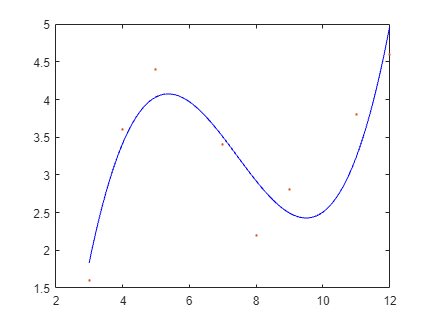


% Plot Graph

g1 = [3:0.1:12];
pp1 = polyval(p1, g1);
plot(g1, pp1, 'b')
hold on
plot(x1, y1, '.')
hold off

2) Do the same as in the Question 1 but using the general Z-matrix formulation given on slides 21-25. You should get the same result if you have done it correctly.

x2 = [3, 4, 5, 7, 8, 9, 11, 12]';
y2 = [1.6, 3.6, 4.4, 3.4, 2.2, 2.8, 3.8, 4.6]';

z2 = [ones(size(x2)) x2 x2.^2 x2.^3];
a2 = (z2'*z2)\(z2'*y2)

a2 =   -11.4887
    7.1438
   -1.0412
    0.0467


3) Calculate the standard error for the 2 power equation models from Example 6 in the lecture notes and decide if one equation is better than the other or not.

% fNon = 2.5384 * x ^ 1.4359;
% fLin = 0.2741 * x ^ 1.9842;

% Data
x3 = [10:10:80]

x3 =     10    20    30    40    50    60    70    80


y3 = [25, 70, 380, 550, 610, 1220, 830, 1450]

y3 =           25          70         380         550         610        1220         830        1450


y3Lin = 0.2741 * x3 .^ 1.9842;
y3Non = 2.5384 * x3 .^ 1.4359;

% Summation to find sr
srLin = 0;
srNon = 0;
for m = 1:length(x3)
    srLin = srLin + (y3(m) - (0.2741 * x3(m) ^ 1.9842))^2;
    srNon = srNon + (y3(m) - (2.5384 * x3(m) ^ 1.4359))^2;
end

% Find Synx: syx = sqrt(sr/(n- (m+1)))
synx_linear = sqrt(srLin/(length(y3) - (1.9842 + 1)))

synx_linear = 262.5244

synx_nonlinear = sqrt(srNon/(length(y3) - (1.4359 + 1)))

synx_nonlinear = 200.0184


% Use My Equation
syms x
eq1 = 0.2741 * x ^ 1.9842;
eq2 = 2.5384 * x ^ 1.4359;

linear = errorCorr(x3, y3, eq1, 1.9842)

linear =   262.5244    0.8088


nonLinear = errorCorr(x3, y3, eq2, 1.9842)

nonLinear =   210.6674    0.8769


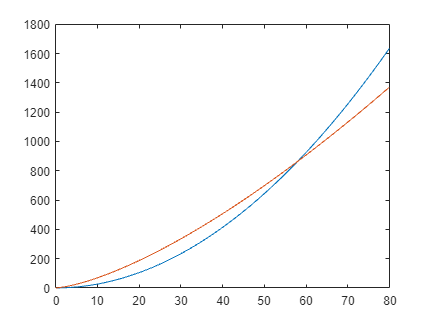


% Plot Graph
xP3 = [0:0.5:80];
y3LinG = 0.2741 * xP3 .^ 1.9842;
y3NonG = 2.5384 * xP3 .^ 1.4359;

plot(xP3, y3LinG, xP3, y3NonG);

4) For the following data use polynomial regression to get an equation that predicts the dissolved oxygen concentration as a function of temperature for the case where the chloride concentration is 0. Graph the data and your fitting equation.

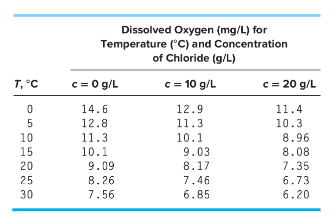

T4 = [0:5:30];
c4 = [14.6, 12.8, 11.3, 10.1, 9.09, 8.26, 7.56];
p42 = polyfit(T4, c4, 2)

p42 =     0.0044   -0.3634   14.5519


p43 = polyfit(T4, c4, 3)

p43 =    -0.0001    0.0073   -0.3956   14.6002



% See standard error for 2
syms x
eq1 = p42(1) * x^2 + p42(2) * x + p42(3);
errorCorr(T4, c4, eq1, 2)

ans =     0.0596    0.9996



% See standard error for 3
syms x
eq2 = p43(1) * x^3 + p43(2) * x^2 + p43(3) * x + p43(4);
errorCorr(T4, c4, eq2, 3)

ans =     0.0083    1.0000


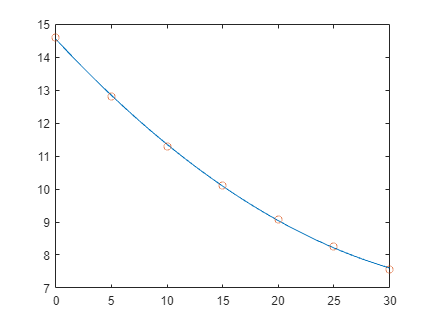


plot4 = [0:0.5:30];
p4v = polyval(p4, plot4);
plot(plot4, p4v);
hold on
plot(T4, c4, "o")
hold off

5) For the data from Question 4 use multiple linear regression to predict the dissolved oxygen concentration as a function of temperature and chloride concentration (**Hint: Make a new table of values**). Plot the data and your equation then use your equation to predict the dissolved oxygen concentration when the chloride concentration is 15 g/L and temperature is 12oC

Oxygen estimated to be 9.4543 mg/L

T5 = [0:5:30];
c05 = [14.6, 12.8, 11.3, 10.1, 9.09, 8.26, 7.56];
c105 = [12.9, 11.3, 10.1, 9.03, 8.17, 7.46, 6.85];

6) Use multiple linear regression to fit the following data. Also calculate the standard error and correlation coefficient.

Function

function err = errorCorr(a, b, eq, no)
% a is array x, b is array y, eq is syms with var x , y, no is no. of
% polynomials
    sr = 0;
    st = 0;

    for m = 1:length(a)
        A = a(m);
        syms x
        sr = sr + (b(m) - (subs(eq, x, A)))^2;
        st = st + (b(m) - mean(b))^2;
    end

    % Finding r2 (r2 = (st - sr)/st)
    r2 = 1 - (sr/st);

    % Finding synx (syx = sqrt(sr/(n- (m+1))))
    synx = sqrt(sr/(length(b) - (no + 1)));

    % Return both synx, r2
    err = [double(synx), double(r2)];
end

function reg = betterPolyfit(x1, x2, y)
    
end